%User note: ignore column headers warning, code runs succesfully (and
%modifications are desirable)

clear
clearvars
clc

%LOAD DATA

filename = 'Data - Global.xlsx';

Data2014 = readmatrix(filename,"Sheet","2014");

Data2014 =        NaN   40.5000   31.7000   39.2000   39.4000   64.6000   61.3000   37.4000   45.5000   29.0000   40.5000   58.2000   30.3000   39.4000   41.2000   41.7000   44.3000   32.9000   32.9000   30.6000   66.3000   48.4000   45.8000   43.4000   41.3000   45.1000   51.7000   65.5000   33.7000   34.1000   36.4000   56.8000   67.5000   59.5000   41.1000   60.3000   33.5000   45.9000   36.7000   25.1000   34.8000   47.0000   56.8000   37.0000   32.4000   63.3000   61.8000   51.2000   39.2000   62.2000
       NaN   20.4000   16.7000   31.1000   32.7000   45.5000   45.5000   21.8000   27.1000   19.7000   33.7000   45.2000   18.1000   25.5000   20.5000   30.8000   37.1000   23.5000   24.5000   24.5000   46.0000   32.8000   47.3000   27.6000   33.3000   36.4000   39.9000   49.5000   21.3000   26.0000   21.7000   46.3000   53.8000   44.8000   28.0000   51.7000   27.0000   32.0000   24.8000   15.4000   18.6000   42.2000   51.3000   30.4000   31.2000   50.0000   49.1000   40.1000   25.70

Data2016 = readmatrix(filename,"Sheet","2016");
Data2018 = readmatrix(filename,"Sheet","2018");
Data2020 = readmatrix(filename,"Sheet","2020");
Data2022 = readmatrix(filename,"Sheet","2022");

%LOAD DATA for this code run (change for year)
year_number=2022; %change for year
disp('Year of 2022') %change for year

Year of 2022


Data=Data2022; %change for year

INPUT=Data(1,2:116);

INPUT =    35.3000   26.7000   21.1000   35.6000   34.3000   59.3000   59.6000   35.3000   41.6000   26.5000   33.7000   55.3000   27.6000   38.7000   36.5000   40.4000   42.2000   25.2000   22.2000   31.4000   23.0000   62.5000   43.7000   57.5000   39.2000   38.2000   42.7000   51.3000   62.8000   32.7000   29.7000   29.2000   28.6000   60.7000   22.6000   64.5000   60.9000   39.6000   60.9000   27.8000   43.0000   24.5000   20.0000   27.5000   46.9000   55.9000   44.1000   36.9000   55.8000   57.3000


OUTPUT=Data(2,2:116);

OUTPUT =    13.6000    6.7000    6.8000   21.6000   18.9000   35.0000   40.7000    7.6000   14.3000   12.9000   21.4000   38.5000    1.7000   18.4000   11.2000   24.7000   36.9000    5.4000    2.5000    9.6000    7.2000   39.0000   24.3000   53.1000   19.2000   19.1000   28.5000   41.1000   49.1000   12.7000   10.9000   16.2000   11.1000   39.7000   10.0000   49.3000   49.0000   16.2000   53.5000   13.8000   26.1000   11.1000    3.2000    7.0000   32.8000   43.0000   29.1000   18.8000   41.3000   43.2000


FSI=Data(3,2:116);

FSI =    56.7000   72.2000   88.1000   47.9000   67.0000   22.7000   25.4000   73.1000   66.6000   84.5000   68.7000   31.9000   72.5000   73.0000   56.1000   73.9000   51.6000   90.5000   95.4000   80.5000   96.0000   20.1000   43.2000   66.9000   78.4000   41.0000   49.3000   56.9000   18.1000   62.8000   69.1000   83.6000   70.8000   37.7000   99.3000   15.1000   30.9000   71.8000   23.6000   63.0000   55.8000   77.5000   99.6000   78.7000   50.8000   17.1000   75.3000   66.6000   20.8000   42.6000



Headers_data = readtable(filename,"Sheet","2022") %change for year

Headers_data = 3×116 table
                            Var1                            Albania    Algeria    Angola    Argentina    Armenia    Australia    Austria    Azerbaijan    Bahrain    Bangladesh    Belarus    Belgium    Benin    BosniaAndHerzegovina    Botswana    Brazil    Bulgaria    BurkinaFaso    Burundi    Cambodia    Cameroon    Canada    Chile    China    Colombia    CostaRica    Croatia    Cyprus    Denmark    DominicanRepublic    Ecuador

Countries=Headers_data.Properties.VariableNames;
Countries(:,1) = [];
Countries=Countries';
Countries = cellstr(Countries);

Countries = 115×1 cell array
    {'Albania'             }
    {'Algeria'             }
    {'Angola'              }
    {'Argentina'           }
    {'Armenia'             }
    {'Australia'           }
    {'Austria'             }
    {'Azerbaijan'          }
    {'Bahrain'             }
    {'Bangladesh'          }
    {'Belarus'             }
    {'Belgium'             }
    {'Benin'               }
    {'BosniaAndHerzegovina'}
    {'Botswana'            }
    {'Brazil'              }
    {'Bulgaria'            }
    {'BurkinaFaso'         }
    {'Burundi'             }
    {'Cambodia'            }
    {'Cameroon'            }
    {'Canada'              }
    {'Chile'               }
    {'China'               }
    {'Colombia'            }
    {'CostaRica'           }
    {'Croatia'             }
    {'Cyprus'              }
    {'Denmark'             }
    {'DominicanRepublic'   }


dx = 0.5; dy = 0.5; % displacement so the text does not overlay the data points


%PRESENT DATA
F1=figure(1);
scatter(INPUT,OUTPUT)
text(INPUT+dx, OUTPUT+dy, Countries,'FontSize',5);
title('Relationship between Innovation Inputs and Outputs', num2str(year_number))
xlabel('Innovation Input Score (from GII data)') 
ylabel('Innovation Output Score (from GII data)')

xlim([15 75])
ylim([0 65])


F2=figure(2);
scatter(INPUT,FSI)
text(INPUT+dx, FSI+dy, Countries,'FontSize',5);
title('Relationship between Innovation Inputs and FSI', num2str(year_number))
xlabel('Innovation Input Score (from GII data)') 
ylabel('Fragile States Index (from FSI data)') 

xlim([20 75])
ylim([10 100])


F3=figure(3);
scatter(OUTPUT,FSI)
text(OUTPUT+dx, FSI+dy, Countries,'FontSize',5);
title('Relationship between Innovation Outputs and FSI', num2str(year_number))
xlabel('Innovation Output Score (from GII data)') 
ylabel('Fragile States Index (from FSI data)')

xlim([1 65])
ylim([10 115])

%Converting factor variables from continuous to nominal data for ANOVA
%Where 1 is least, 3 is most 
 
FSI_edges=[min(FSI) min(FSI)+(1/3.*(max(FSI)-min(FSI))) min(FSI)+(2/3.*(max(FSI)-min(FSI))) max(FSI)];
INPUT_edges=[min(INPUT) min(INPUT)+(1/3.*(max(INPUT)-min(INPUT))) min(INPUT)+(2/3.*(max(INPUT)-min(INPUT))) max(INPUT)];
OUTPUT_edges=[min(OUTPUT) min(OUTPUT)+(1/3.*(max(OUTPUT)-min(OUTPUT))) min(OUTPUT)+(2/3.*(max(OUTPUT)-min(OUTPUT))) max(OUTPUT)];

FSI_categories = discretize(FSI,FSI_edges);
INPUT_categories = discretize(INPUT,INPUT_edges);
OUTPUT_categories = discretize(OUTPUT,OUTPUT_edges);

%Running ANOVA
disp('Relationship test between FSI and INPUT')

Relationship test between FSI and INPUT


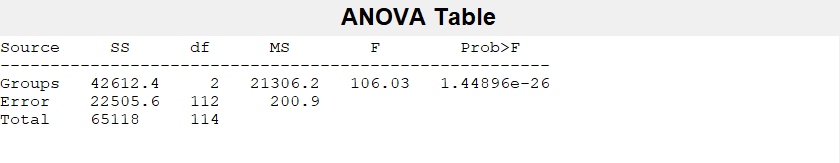

[p_1]=anova1(FSI, INPUT_categories);

disp('Relationship test between Output and Input')

Relationship test between Output and Input


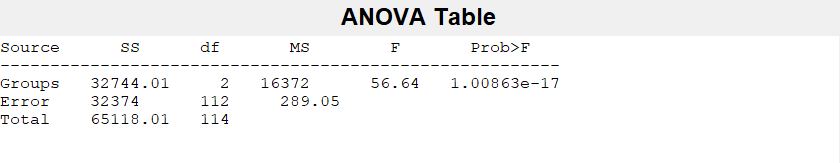

[p_2]=anova1(FSI, OUTPUT_categories);

disp('Relationship test between Input and Output')

Relationship test between Input and Output


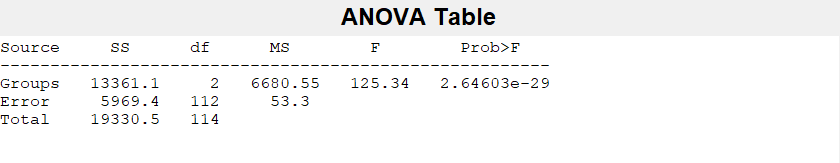

[p_3]=anova1(INPUT, OUTPUT_categories);

disp('Relationship test between Input and Output')

Relationship test between Input and Output


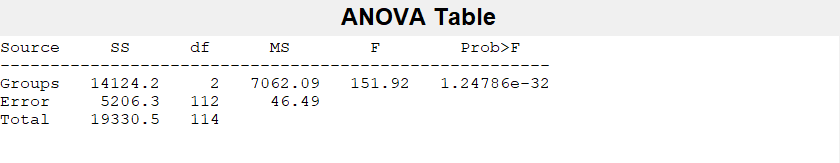

[p_4]=anova1(INPUT, FSI_categories);

disp('Relationship test between Output and FSI')

Relationship test between Output and FSI


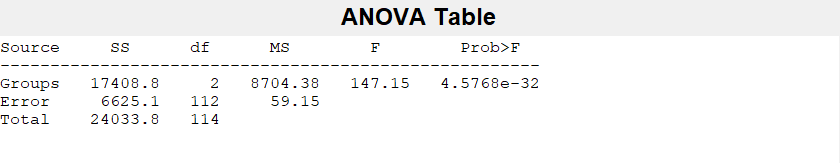

[p_5]=anova1(OUTPUT, INPUT_categories);

disp('Relationship test between Output and Input')

Relationship test between Output and Input


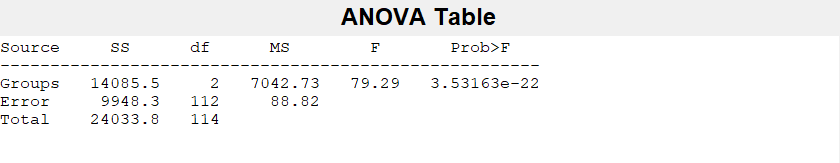

[p_6]=anova1(OUTPUT, FSI_categories);


%Converting to columns for correlation
FSI = FSI.';
INPUT = INPUT.';
OUTPUT = OUTPUT.';

% if p_1<0.05
SpearmanCoefficientFSIvINPUT = corr(FSI, INPUT, 'type', 'Spearman', 'Rows','complete')

SpearmanCoefficientFSIvINPUT = -0.8805

KendallCoefficientFSIvINPUT = corr(FSI, INPUT, 'type', 'Kendall', 'Rows','complete')

KendallCoefficientFSIvINPUT = -0.7038

PearsonCoefficientFSIvINPUT = corr(FSI, INPUT, 'type', 'Pearson', 'Rows','complete')

PearsonCoefficientFSIvINPUT = -0.8861

% else
% SpearmanCoefficientFSIvINPUT = NaN ;
% KendallCoefficientFSIvINPUT = NaN ;
% PearsonCoefficientFSIvINPUT = NaN ; 
% end 

% if p_4<0.05
SpearmanCoefficientINPUTvFSI = corr(INPUT, FSI, 'type', 'Spearman', 'Rows','complete')

SpearmanCoefficientINPUTvFSI = -0.8805

KendallCoefficientINPUTvFSI = corr(INPUT, FSI, 'type', 'Kendall', 'Rows','complete')

KendallCoefficientINPUTvFSI = -0.7038

PearsonCoefficientINPUTvFSI = corr(INPUT, FSI, 'type', 'Pearson', 'Rows','complete')

PearsonCoefficientINPUTvFSI = -0.8861

% else
% SpearmanCoefficientINPUTvFSI = NaN ;
% KendallCoefficientINPUTvFSI = NaN ;
% PearsonCoefficientINPUTvFSI = NaN ; 
% end 

% if p_2<0.05
SpearmanCoefficientFSIvOUTPUT = corr(FSI, OUTPUT, 'type', 'Spearman', 'Rows','complete')

SpearmanCoefficientFSIvOUTPUT = -0.8019

KendallCoefficientFSIvOUTPUT = corr(FSI, OUTPUT, 'type', 'Kendall', 'Rows','complete')

KendallCoefficientFSIvOUTPUT = -0.5999

PearsonCoefficientFSIvOUTPUT = corr(FSI, OUTPUT, 'type', 'Pearson', 'Rows','complete')

PearsonCoefficientFSIvOUTPUT = -0.7987

% else
% SpearmanCoefficientFSIvOUTPUT = NaN ;
% KendallCoefficientFSIvOUTPUT = NaN ;
% PearsonCoefficientFSIvOUTPUT = NaN ; 
% end 

% if p_6<0.05
SpearmanCoefficientOUTPUTvFSI = corr(OUTPUT, FSI, 'type', 'Spearman', 'Rows','complete')

SpearmanCoefficientOUTPUTvFSI = -0.8019

KendallCoefficientOUTPUTvFSI = corr(OUTPUT, FSI, 'type', 'Kendall', 'Rows','complete')

KendallCoefficientOUTPUTvFSI = -0.5999

PearsonCoefficientOUTPUTvFSI = corr(OUTPUT, FSI, 'type', 'Pearson', 'Rows','complete')

PearsonCoefficientOUTPUTvFSI = -0.7987

% else
% SpearmanCoefficientOUTPUTvFSI = NaN ;
% KendallCoefficientOUTPUTvFSI = NaN ;
% PearsonCoefficientOUTPUTvFSI = NaN ; 
% end 

% if p_3<0.05 & p_5<0.05
SpearmanCoefficientOUTPUTvINPUT = corr(OUTPUT, INPUT, 'type', 'Spearman', 'Rows','complete')

SpearmanCoefficientOUTPUTvINPUT = 0.9010

KendallCoefficientOUTPUTvINPUT = corr(OUTPUT, INPUT, 'type', 'Kendall', 'Rows','complete')

KendallCoefficientOUTPUTvINPUT = 0.7257

PearsonCoefficientOUTPUTvINPUT = corr(OUTPUT, INPUT, 'type', 'Pearson', 'Rows','complete')

PearsonCoefficientOUTPUTvINPUT = 0.9152

% else
% SpearmanCoefficientOUTPUTvINPUT = NaN ;
% KendallCoefficientOUTPUTvINPUT = NaN ;
% PearsonCoefficientOUTPUTvINPUT = NaN ; 
% end 

% if p_5<0.05
SpearmanCoefficientINPUTvOUTPUT = corr(INPUT, OUTPUT, 'type', 'Spearman', 'Rows','complete')

SpearmanCoefficientINPUTvOUTPUT = 0.9010

KendallCoefficientINPUTvOUTPUT = corr(INPUT, OUTPUT, 'type', 'Kendall', 'Rows','complete')

KendallCoefficientINPUTvOUTPUT = 0.7257

PearsonCoefficientINPUTvOUTPUT = corr(INPUT, OUTPUT, 'type', 'Pearson', 'Rows','complete')

PearsonCoefficientINPUTvOUTPUT = 0.9152

% else
% SpearmanCoefficientINPUTvOUTPUT = NaN ;
% KendallCoefficientINPUTvOUTPUT = NaN ;
% PearsonCoefficientINPUTvOUTPUT = NaN ; 
% end 


%RESULTS TABLE

column_names={'ANOVA variable',  'SpearmanCoefficient', 'KendallCoefficient', 'PearsonCoefficient'};
row_names={'FSIvINPUT','FSIvOUTPUT','INPUTvsOUTPUT','INPUTvsFSI','OUTPUTvsFSI','OUTPUTvsINPUT'};
values= {p_1, SpearmanCoefficientFSIvINPUT, KendallCoefficientFSIvINPUT, PearsonCoefficientFSIvINPUT; p_2, SpearmanCoefficientFSIvOUTPUT, KendallCoefficientFSIvOUTPUT, PearsonCoefficientFSIvOUTPUT; p_3, SpearmanCoefficientOUTPUTvINPUT, KendallCoefficientOUTPUTvINPUT, PearsonCoefficientOUTPUTvINPUT; p_4, SpearmanCoefficientINPUTvFSI, KendallCoefficientINPUTvFSI, PearsonCoefficientINPUTvFSI; p_6, SpearmanCoefficientOUTPUTvFSI, KendallCoefficientOUTPUTvFSI, PearsonCoefficientOUTPUTvFSI; p_5, SpearmanCoefficientINPUTvOUTPUT, KendallCoefficientINPUTvOUTPUT, PearsonCoefficientINPUTvOUTPUT};

T=cell2table(values, 'RowNames', row_names, 'VariableNames', column_names)

T = 6×4 table
                     ANOVA variable    SpearmanCoefficient    KendallCoefficient    PearsonCoefficient
                     ______________    ___________________    __________________    __________________

    FSIvINPUT           1.449e-26           -0.88051               -0.70381              -0.88607     
    FSIvOUTPUT         1.0086e-17           -0.80192               -0.59991              -0.79871     
    INPUTvsOUTPUT       2.646e-29            0.90097                0.72573               0.91522     
    INPUTvsFSI         1.2479e-32           -0.88051               -0.70381              -0.88607     
    OUTPUTvsFSI        3.5316e-22           -0.80192               -0.59991              -0.79871     
    OUTPUTvsINPUT      4.5